# Parameter Analysis

uses the **minCOT.m** function to analyze parameters of interest:

- **forward speed (xdot_target)**

- **leg inertia (I)**

- **spring constant (k)**

- **damping constant (c)**

clearvars; clc; close all;

### **Analysis 1: Forward Speed vs. Leg Inertia**

% add necessary paths
addpath('functions/multiOpt');
addpath('functions/sharedFuncs');
addpath('warmStartTemplates');
addpath('data');

% some constants
m = 1;
k = 15;
c = 0.4;

speeds = 0.25:0.25:3;
inertias = 1e-2:1e-2:7e-2;

#### Run optimization sweep

Several things added:

- isNotExpected function to rerun in case of weird output (happens but not sure why)

- Creating a mesh by creating rows then appending rows together

- first block is nonparallelized code (written by me)

- second block is parallelized code (written by gemini, requiring the parallel computing toolbox)

% NON PARALLELIZED VERSION
num_speeds = numel(speeds);
num_inertias = numel(inertias);

running_COTs = zeros(num_inertias, num_speeds);
hopping_COTs = zeros(num_inertias, num_speeds);
next_guess = 0;

for I_idx=1:num_inertias
    I = inertias(I_idx);
    runCOT_tmpRow = zeros(1, num_speeds);
    hopCOT_tmpRow = zeros(1, num_speeds);
    for s_idx=1:num_speeds
        speed = speeds(s_idx);

        % to recompute if weird value appears
        [runCOT, ~, ~, ~, ~] =...
            robustMinCOT('r', speed, k, c, I, 0, runCOT_tmpRow);
        runCOT_tmpRow(s_idx) = runCOT;

        [hopCOT, ~, ~, ~, ~] =...
            robustMinCOT('h', speed, k, c, I, 0, hopCOT_tmpRow);
        hopCOT_tmpRow(s_idx) = hopCOT;
        
    end
    running_COTs(I_idx, :) = runCOT_tmpRow;
    hopping_COTs(I_idx, :) = hopCOT_tmpRow;
end

% PARALLELIZED VERSION (GENERATED WITH GEMINI FROM THE CODE ABOVE)

num_inertias = length(inertias);
num_speeds   = length(speeds);

% Preallocate output matrices
running_COTs = zeros(num_inertias, num_speeds);
hopping_COTs = zeros(num_inertias, num_speeds);

% cluster = parcluster('Processes');
% cluster.NumWorkers = num_inertias;
% saveProfile(cluster);
% parpool(num_inertias);
parfor I_idx = 1:num_inertias
    next_guess_run = 0;
    next_guess_hop = 0;

    I = inertias(I_idx);
    
    % Preallocate local row vectors for this worker's iteration
    runCOT_tmpRow = zeros(1, num_speeds);
    hopCOT_tmpRow = zeros(1, num_speeds);
    
    for s_idx = 1:num_speeds
        speed = speeds(s_idx);
        
        % --- Running COT ---
        % Pass the preallocated slice up to the current index
        [runCOT, ~, ~, ~, ~, next_guess_run] = ...
            robustMinCOT('r', speed, k, c, I, next_guess_run, []);
        runCOT_tmpRow(s_idx) = runCOT;
        
        % --- Hopping COT ---
        % Pass the preallocated slice up to the current index
        [hopCOT, ~, ~, ~, ~, next_guess_hop] = ...
            robustMinCOT('h', speed, k, c, I, next_guess_hop, []);
        hopCOT_tmpRow(s_idx) = hopCOT;
    end
    
    % Assign the clean rows to the global matrices
    running_COTs(I_idx, :) = runCOT_tmpRow;
    hopping_COTs(I_idx, :) = hopCOT_tmpRow;
end

Mode: r | Speed: 0.25 | k, c, I: 15 0.40 0.07000
using warm start template
Mode: r | Speed: 0.25 | k, c, I: 15 0.40 0.06000
using warm start template
Mode: r | Speed: 0.25 | k, c, I: 15 0.40 0.05000
using warm start template
Mode: r | Speed: 0.25 | k, c, I: 15 0.40 0.03000
using warm start template
Mode: r | Speed: 0.25 | k, c, I: 15 0.40 0.02000
using warm start template
Mode: r | Speed: 0.25 | k, c, I: 15 0.40 0.04000
using warm start template
Mode: r | Speed: 0.25 | k, c, I: 15 0.40 0.01000
using warm start template
Mode: h | Speed: 0.25 | k, c, I: 15 0.40 0.05000
Mode: h | Speed: 0.25 | k, c, I: 15 0.40 0.03000
using warm start template
using warm start template
Mode: h | Speed: 0.25 | k, c, I: 15 0.40 0.02000
using warm start template
Mode: h | Speed: 0.25 | k, c, I: 15 0.40 0.04000
using warm start template
Mode: h | Speed: 0.25 | k, c, I: 15 0.40 0.07000
using warm start template
Mode: h | Speed: 0.25 | k, c, I: 15 0.40 0.01000
using warm start template
Mode: h | Speed: 0.25 | k

**The data generated from the code above is stored in dataspaces/speedInertiaSweep.mat*

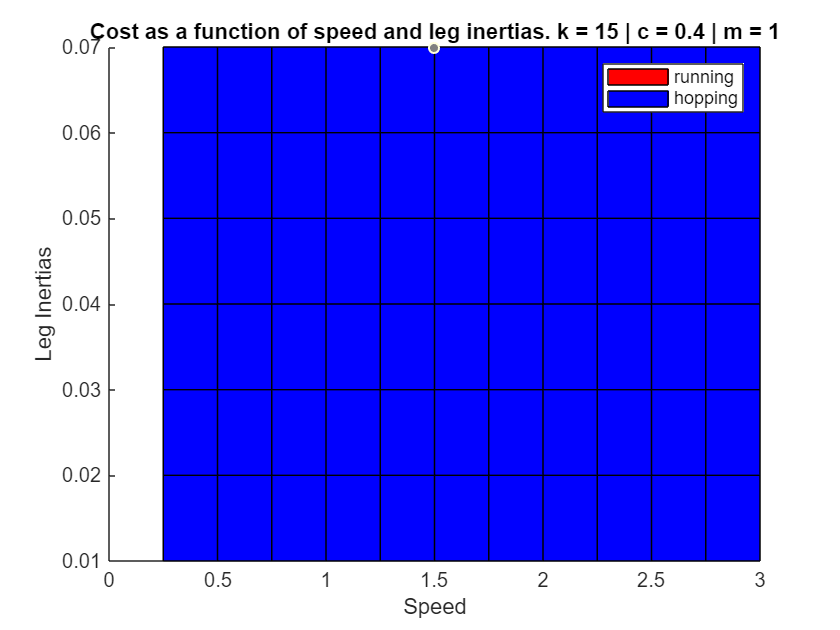

figure;
hold on;
surf(speeds, inertias, running_COTs, 'FaceColor', 'red');
surf(speeds, inertias, hopping_COTs,'FaceColor', 'blue');
xlabel("Speed");
ylabel("Leg Inertias");
zlabel("Cost");
title("Cost as a function of speed and leg inertias. " + ...
    "k = " + k + " | c = " + c  + " | m = " + m);
legend("running", "hopping");
hold off;

#### Results:

The plot shows that running is more favorable at higher leg inertias. However, the plot also shows that hopping is more favorable at higher speeds. Thus, the next step is to examine the individual portions of cost and step period to examine which elements of the gait are driving this trend.

#### Analysis 1.2: Cost of phases and time periods across various speeds

clc; clear; close all;

m = 1;
k = 15;
c = 0.4;
I = 4.63e-2;

speeds = 0.25:0.25:7;

% BASED ON PARALLELIZAITON CODE ABOVE

num_speeds = length(speeds);

% 1. Preallocate matrices for parallel efficiency and sliced variable compliance
runCOTs = zeros(1, num_speeds);
run_stance_costs = zeros(1, num_speeds);
run_flight_costs = zeros(1, num_speeds);
run_stance_periods = zeros(1, num_speeds);
run_flight_periods = zeros(1, num_speeds);

hopCOTs = zeros(1, num_speeds);
hop_stance_costs = zeros(1, num_speeds);
hop_flight_costs = zeros(1, num_speeds);
hop_stance_periods = zeros(1, num_speeds);
hop_flight_periods = zeros(1, num_speeds);

cluster = parcluster('Processes');
cluster.NumWorkers = num_speeds;
saveProfile(cluster);
parpool(num_speeds);

Starting parallel pool (parpool) using the 'Processes' profile ...
14-Jul-2026 15:08:35: Job Queued. Waiting for parallel pool job with ID 12 to start ...
14-Jul-2026 15:09:37: Job Queued. Waiting for parallel pool job with ID 12 to start ...
Connected to parallel pool with 28 workers.


parfor s_idx = 1:num_speeds
    speed = speeds(s_idx);

    next_guess_run = 0;
    next_guess_hop = 0;
    
    % --- Running COT ---
    [runCOT, run_stance_cost, run_flight_cost, run_tstance, run_tflight, next_guess_run] = ...
        robustMinCOT('r', speed, k, c, I, next_guess_run, []);
    runCOTs(s_idx) = runCOT;
    run_stance_costs(s_idx) = run_stance_cost;
    run_flight_costs(s_idx) = run_flight_cost;
    run_stance_periods(s_idx) = run_tstance;
    run_flight_periods(s_idx) = run_tflight;
    
    % --- Hopping COT ---
    % Pass the preallocated slice up to the current index
    [hopCOT, hop_stance_cost, hop_flight_cost, hop_tstance, hop_tflight, next_guess_hop] = ...
        robustMinCOT('h', speed, k, c, I, next_guess_hop, []);
    hopCOTs(s_idx) = hopCOT;
    hop_stance_costs(s_idx) = hop_stance_cost;
    hop_flight_costs(s_idx) = hop_flight_cost;
    hop_stance_periods(s_idx) = hop_tstance;
    hop_flight_periods(s_idx) = hop_tflight;
end

Mode: r | Speed: 4.00 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 1.75 | k, c, I: 15 0.40 0.04630
Mode: r | Speed: 4.25 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 6.75 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 3.00 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 2.50 | k, c, I: 15 0.40 0.04630
Mode: r | Speed: 2.25 | k, c, I: 15 0.40 0.04630
Mode: r | Speed: 6.50 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 0.25 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 3.25 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 1.50 | k, c, I: 15 0.40 0.04630
Mode: r | Speed: 1.00 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 1.25 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 5.25 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 4.75 | k, c, I: 15 0.40 0.04630
using

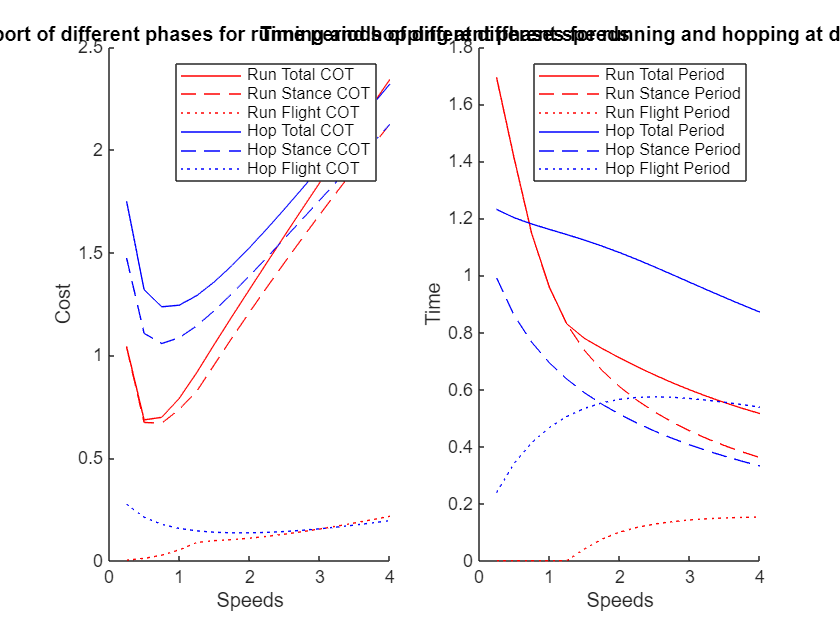

%close all;
figure;
subplot(1, 2, 1);
hold on;
plot(speeds, runCOTs, "r-");
plot(speeds, run_stance_costs, "r--");
plot(speeds, run_flight_costs, "r:");

plot(speeds, hopCOTs, "b-");
plot(speeds, hop_stance_costs, "b--");
plot(speeds, hop_flight_costs, "b:");

xlabel Speeds;
ylabel Cost;
legend("Run Total COT", "Run Stance COT", "Run Flight COT",...
       "Hop Total COT", "Hop Stance COT", "Hop Flight COT");
title("Cost of transport of different phases for running and hopping at different speeds");
hold off;

subplot(1, 2, 2);
hold on;
plot(speeds, (run_stance_periods + run_flight_periods), "r-");
plot(speeds, run_stance_periods, "r--");
plot(speeds, run_flight_periods, "r:");

plot(speeds, (hop_stance_periods + hop_flight_periods), "b-");
plot(speeds, hop_stance_periods, "b--");
plot(speeds, hop_flight_periods, "b:");

xlabel Speeds;
ylabel Time;
legend("Run Total Period", "Run Stance Period", "Run Flight Period",...
       "Hop Total Period", "Hop Stance Period", "Hop Flight Period");
title("Time periods of different phases for running and hopping at different speeds");

hold off;

### Analysis 2: Forward Speed vs. Spring Constant

clc; clear; close all;

% some constants
clc; clear; close all;

m = 1;
k = 15;
c = 0.4;
I = 4.63e-2;

speeds = 1:0.5:7;
ks = 10:2.5:20;

#### Run optimization sweep:

- The exact same code block as above but with spring constant varying instead of leg inertia

% BASED ON PARALLELIZE CODE IN (1)

num_ks = length(ks);
num_speeds   = length(speeds);

% Preallocate output matrices
running_COTs = zeros(num_ks, num_speeds);
hopping_COTs = zeros(num_ks, num_speeds);

% cluster = parcluster('Processes');
% cluster.NumWorkers = num_ks;
% saveProfile(cluster);
% parpool(num_ks);
parfor k_idx = 1:num_ks
    next_guess_run = 0;
    next_guess_hop = 0;

    k = ks(k_idx);
    
    % Preallocate local row vectors for this worker's iteration
    runCOT_tmpRow = zeros(1, num_speeds);
    hopCOT_tmpRow = zeros(1, num_speeds);
    
    for s_idx = 1:num_speeds
        speed = speeds(s_idx);
        
        % --- Running COT ---
        % Pass the preallocated slice up to the current index
        [runCOT, ~, ~, ~, ~, next_guess_run] = ...
            robustMinCOT('r', speed, k, c, I, next_guess_run, []);
        runCOT_tmpRow(s_idx) = runCOT;
        
        % --- Hopping COT ---
        % Pass the preallocated slice up to the current index
        [hopCOT, ~, ~, ~, ~, next_guess_hop] = ...
            robustMinCOT('h', speed, k, c, I, next_guess_hop, []);
        hopCOT_tmpRow(s_idx) = hopCOT;
    end
    
    % Assign the clean rows to the global matrices
    running_COTs(k_idx, :) = runCOT_tmpRow;
    hopping_COTs(k_idx, :) = hopCOT_tmpRow;
end

Mode: r | Speed: 1.00 | k, c, I: 20 0.40 0.04630
using warm start template
Mode: r | Speed: 1.00 | k, c, I: 10 0.40 0.04630
using warm start template
Mode: r | Speed: 1.00 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: r | Speed: 1.00 | k, c, I: 1.250000e+01 0.40 0.04630
using warm start template
Mode: r | Speed: 1.00 | k, c, I: 1.750000e+01 0.40 0.04630
using warm start template
Mode: h | Speed: 1.00 | k, c, I: 10 0.40 0.04630
using warm start template
Mode: h | Speed: 1.00 | k, c, I: 15 0.40 0.04630
using warm start template
Mode: h | Speed: 1.00 | k, c, I: 1.250000e+01 0.40 0.04630
using warm start template
Mode: h | Speed: 1.00 | k, c, I: 20 0.40 0.04630
using warm start template
Mode: h | Speed: 1.00 | k, c, I: 1.750000e+01 0.40 0.04630
using warm start template
Mode: r | Speed: 1.50 | k, c, I: 10 0.40 0.04630
Mode: r | Speed: 1.50 | k, c, I: 1.250000e+01 0.40 0.04630
Mode: r | Speed: 1.50 | k, c, I: 15 0.40 0.04630
Mode: r | Speed: 1.50 | k, c, I: 20 0.40 0.04630
Mode

figure;

hold on;
surf(speeds, ks, running_COTs, 'FaceColor', 'red');
surf(speeds, ks, hopping_COTs,'FaceColor', 'blue');
xlabel("Speed");
ylabel("Spring Constant (k)");
zlabel("Cost");
title("Cost as a function of speed and spring constants. " + ...
    "I = " + I + " | c = " + c  + " | m = " + m);
legend("running", "hopping");
hold off;

rmpath('functions/multiOpt');
rmpath('functions/sharedFuncs');
rmpath('warmStartTemplates');
rmpath('data');